%配送中心问题
clear;clc
T1=readtable('配送中心.xls','Sheet',"城市及销售中心数据");
T2=readtable('配送中心.xls','Sheet','全省公路路线');

temp1=table2array(T1(:,1:4));
temp2=table2array(T2(:,1:2));

%做关联矩阵
%矩阵M为提取两个表中每个公路起点到终点的位移
E=zeros(size(temp1,1),size(temp1,1));
for i=1:size(temp2) 
    r=temp2(i,1);
    c=temp2(i,2);
    a=temp1(r,2:3);
    b=temp1(c,2:3);
    E(r,c)=distance(a,b); 
    E(c,r)=E(r,c);
end

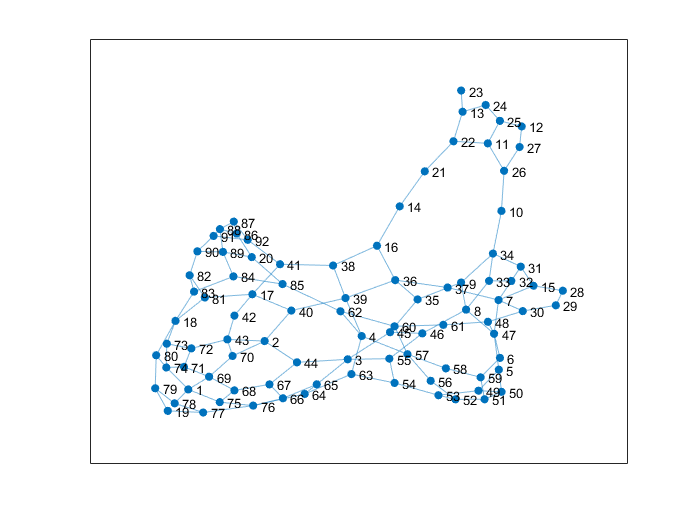

G1=graph(E);
plot(G1);

M=E;
n=size(M,1);
%把零改成无穷大
%Floyd算法
for i=1:n
    for j=1:n
        if M(i,j)==0
            M(i,j)=inf;
        end
    end
end
path=zeros(n);
for k=1:n
	for i=1:n
		for j=1:n
			if M(i,j)>M(i,k)+M(k,j)
				M(i,j)=M(i,k)+M(k,j);
				path(i,j)=k;
			end
		end
	end
end
%把对角线上的元素改成0
for i=1:92
    M(i,i)=0;
end

%(1)为了降低运输成本，配送中心应选在哪个城市
cost=1e9;
site=1;
for i=1:size(M)
    temp=0;
    for j=1:20
        temp=temp+2*M(i,j)*temp1(j,4);%每个城市的运费*距离*销售量的
    end
    if temp<cost%选出成本最小的地点
        site=i;
        cost=temp;
    end
end
disp("配送成本最低的城市为:"+int2str(site))

配送成本最低的城市为:35


disp("配送成本为:"+int2str(cost))

配送成本为:61576


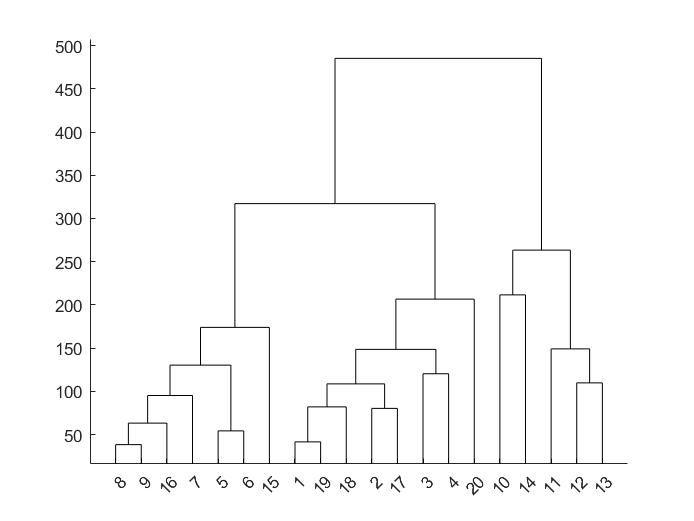

%(2)请为该企业制定一个成本最小的5年产品配送计划：
% 应设立几个配送中心、各设在何处？
%writematrix(M,'距离.xls');
z=linkage(M(1:20,1:20),"average");
h=dendrogram(z);
set(h,'Color','k')

for k=3:6
        fprintf("划分成%d类的结果如下:\n",k)
        T=cluster(z,'maxclust',k);%划分k类
        for i=1:k
            tm=find(T==i);%求第i类的对象
            tm=reshape(tm,1,length(tm));
            fprintf("第%d类的有:",i);
            disp(tm);
        end
        if k==8
            break
        end
    fprintf("*******************");
end

划分成3类的结果如下:


第1类的有:

     5     6     7     8     9    15    16



第2类的有:

     1     2     3     4    17    18    19    20



第3类的有:

    10    11    12    13    14



*******************

划分成4类的结果如下:


第1类的有:

    11    12    13



第2类的有:

    10    14



第3类的有:

     5     6     7     8     9    15    16



第4类的有:

     1     2     3     4    17    18    19    20



*******************

划分成5类的结果如下:


第1类的有:

    10



第2类的有:

    14



第3类的有:

    11    12    13



第4类的有:

     5     6     7     8     9    15    16



第5类的有:

     1     2     3     4    17    18    19    20



*******************

划分成6类的结果如下:


第1类的有:

    20



第2类的有:

     1     2     3     4    17    18    19



第3类的有:

    10



第4类的有:

    14



第5类的有:

    11    12    13



第6类的有:

     5     6     7     8     9    15    16



*******************

function d=distance(a,b)
    d=sqrt(sum((a-b).^2));
end
function cost=costing(n)
    cost=0;
    s=temp1(1:20,4)*12*5;%五年内各地总销量
    for i=1:20
        k=min(M(i,n));%选址中最短路
        cost=cost+2*k*s(i,4);%每个城市的运费*距离*销售量的
    end
end